**Finding the Max Height of a Rocket**

First, lets find the heights accoring to the equation given

t = 0:2:100; %Makes t from 0 to 100 
Height = 2.13* t.^2 -0.0013 * t.^4 + 0.000034 * t.^4.751;
%calculate height values

**Finding Max Height and Position (timewise)**

Luckily, MatLab has built-in functions that calculate the max in an array and, if given a second index, it's position. So, we'll used those to find the maximum height and its position

[maxHeight,maxPosit] = max(Height); 
%finds max value and position of Height
maxHeightTime = t(maxPosit);
%Finds the time based on position of maxPosit

**Display and Plot**

First, we'll be using fprintf to display the max position and time, then we'll be plotting height vs time to check the validity of the statement.

fprintf(['The maximum height of the rocket is ', num2str(maxHeight), ',\noccuring at t = ', num2str(maxHeightTime), ' seconds.']);

The maximum height of the rocket is 1469.5236,
occuring at t = 40 seconds.

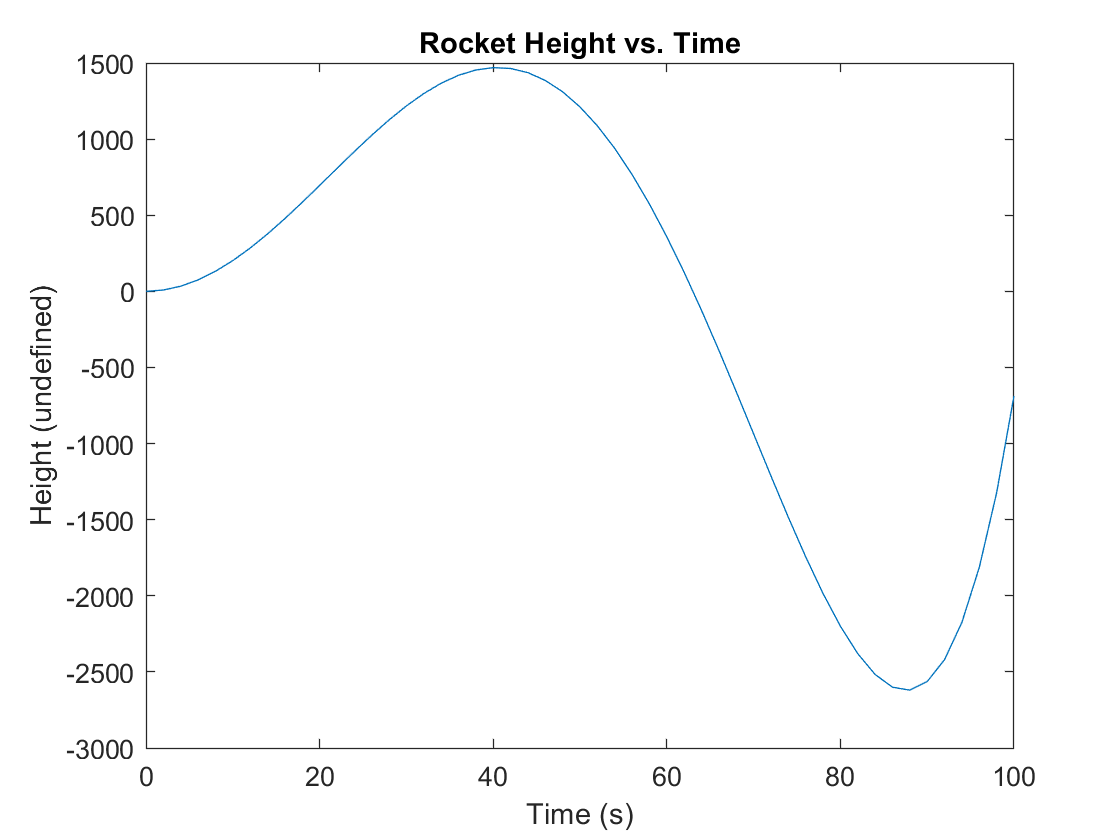

plot(t,Height);
%These next ones are for labelling
title('Rocket Height vs. Time');
xlabel('Time (s)');
ylabel('Height (undefined)');

Note: when the plot goes negative, the rocket has hit the ground

**Hitting the Ground**

To get a more useful plot of height, assuming the ground is at height = 0, we could overwrite all negative values in height to 0 and re-plot

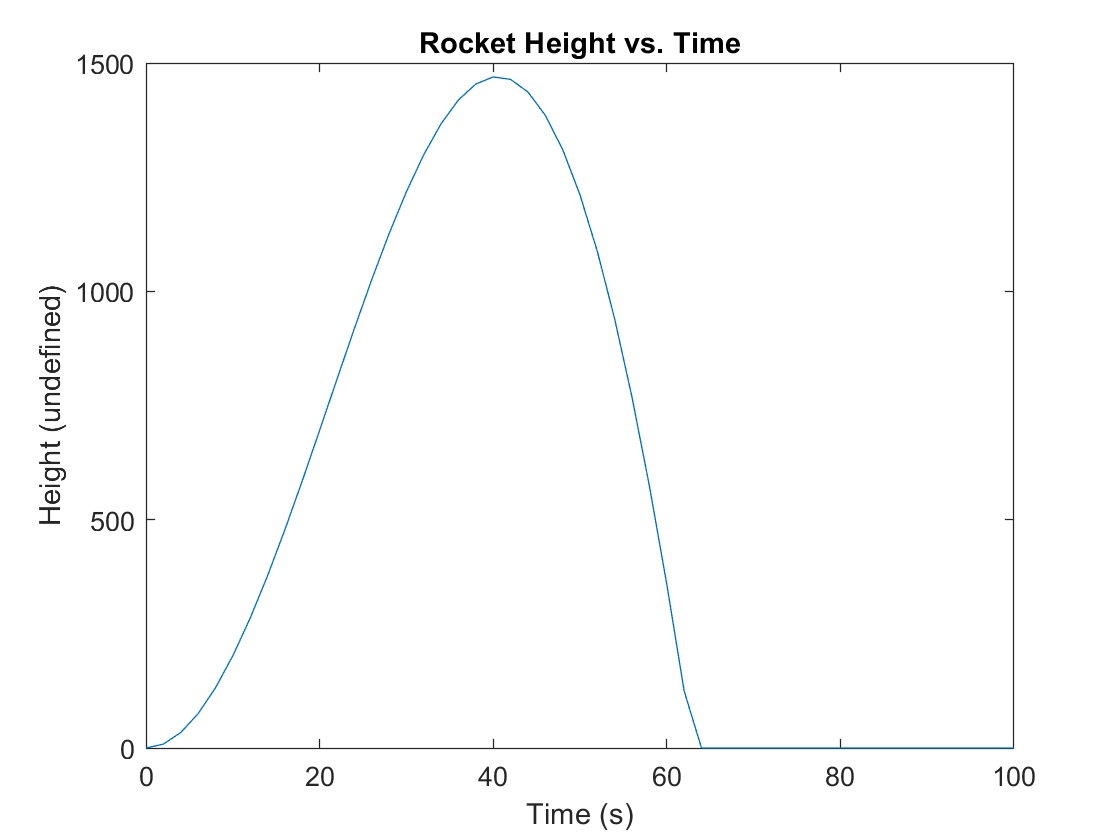

Height(Height < 0) = 0; %replace all values that are negative with 0
plot(t,Height);%re-plot
%These next ones are for labelling
title('Rocket Height vs. Time');
xlabel('Time (s)');
ylabel('Height (undefined)');

Note that the plot is more useful in seeing where our maximum height is. It verifies it is at t = 40 seconds.